% @copyright Jilin University
% Author: hongyu 
% Date : 11/3/2016 
% This demo uses HMM to recognize the human gestures
clear all;
clc; 

load 'training_set_add_min_20.mat';

cluster_number = 10;% also indicate the emission number of the HMM Model
percent = 0.8; % the percentage of the data you want to use to train the data
len_act = [20 20 20 40 80 80 80]; % the samples used to represent the specific activities.
type = 1; %type represnet the traing type of HMM, '0' indict the supervised training and '1' indict the un-surpervised training
num_states = 5;

training_data =Training_set;

cd 'sample_adjust';
%training_data=dowsampling(training_data,5);
training_data=upsampling(training_data,5);
cd .. 


% This file used to test the correctness of the human gesture recognization
% algorithm
% change the time serious data into frequence domain and cluster the
% frequence vector into multiple clusters which could decrease the
% demensions of the data

cd Kmeans_demo;
[index,center,time,freq,power,EMIS_seq,Label_seq,RSS_power]=kmeans_classification(training_data,cluster_number);

x_power = 758

y_power = 80

center =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037

index =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


EMIS_seq =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1  

Label_seq =    1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


cd ..

% visulize the kmeans results


% % visulize the kmeans results


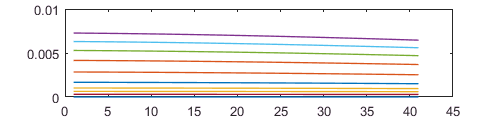

figure('position',[100 100 500 120]);
for i=1:1:cluster_number
plot(center(i,10:50),'linewidth',1);hold on;
end 

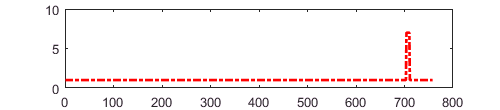



 figure('position',[100 100 500 110]);
 plot(EMIS_seq(1,:),'r-.','linewidth',2); hold on;

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(3,:),'r-.','linewidth',2); hold on;

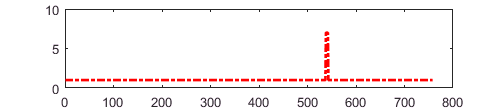

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(21,:),'r-.','linewidth',2); hold on;

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(23,:),'r-.','linewidth',2); hold on;

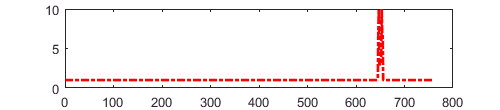

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(41,:),'r-.','linewidth',2); hold on;

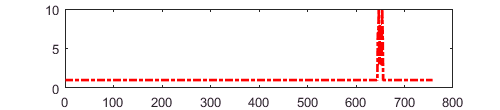

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(43,:),'r-.','linewidth',2); hold on;

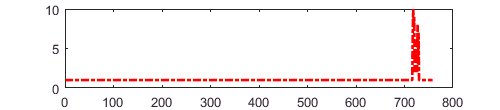

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(61,:),'r-.','linewidth',2); hold on;

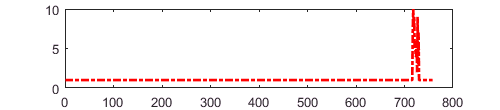

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(63,:),'r-.','linewidth',2); hold on;

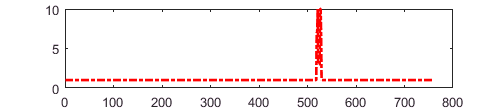

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(101,:),'r-.','linewidth',2); hold on;

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(103,:),'r-.','linewidth',2); hold on;

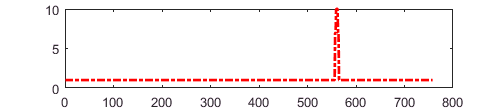

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(181,:),'r-.','linewidth',2); hold on;

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(189,:),'r-.','linewidth',2); hold on;

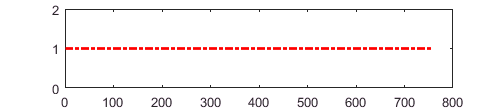

 
 figure('position',[100 100 500 110]);
 plot(EMIS_seq(261,:),'r-.','linewidth',2); hold on;

 figure('position',[100 100 500 110]);
 plot(EMIS_seq(263,:),'r-.','linewidth',2); hold on;

%The HMM demo used in the human gesture recognization applications
cd HMM_demo;

% Partioning the data into traning set and prediction set
[Train_EMIS,Train_label,Pred_EMIS,Pred_label] = HMM_partition(EMIS_seq,Label_seq,percent,len_act);


% visulize partion

TRANS_GUESS = [0.6,0.1,0.1,0.1,0.1; 0.1,0.6,0.1,0.1,0.1; 0.1,0.1,0.6,0.1,0.1; 0.1,0.1,0.1,0.6,0.1; 0.1,0.1,0.1,0.1,0.6];
EMIS_GUESS=ones(num_states,cluster_number)/cluster_number;
[TRANS,EMIS,est_STATE] = HMM_train(Train_EMIS,1,0,TRANS_GUESS,EMIS_GUESS);

TRANS_GUESS

TRANS_GUESS =     0.6000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.6000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.6000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.6000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.6000


EMIS_GUESS

EMIS_GUESS =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


% visulize the un-supervised learning
TRANS

TRANS =     0.8223    0.0000    0.0589    0.0595    0.0593
    0.0847    0.8925    0.0076    0.0077    0.0076
    0.1673    0.0020    0.6221    0.1045    0.1042
    0.1670    0.0020    0.1032    0.6241    0.1037
    0.1671    0.0020    0.1034    0.1042    0.6233


EMIS

EMIS =     1.0000         0         0         0         0         0         0         0         0         0
    0.0000    0.0269    0.1686    0.0181    0.0217    0.0321    0.3966    0.0471    0.0269    0.2622
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0


est_STATE

est_STATE =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

Train_label=Train_label(:,1);
Pred_label_data = Pred_label(:,1);
[likelystates,probs,Pre_label_predict,conf_matrix] = HMM_predict(TRANS,EMIS,Pred_EMIS,est_STATE,Train_label,Pred_label_data);
cd ..;


% Visulization 
likelystates

likelystates =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1    

probs

probs =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9749    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9710    0.9710
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9815    0.9749    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9736    0.9710 


conf_matrix

conf_matrix =      4     0     0     0     0     0     0
     0     4     0     0     0     0     0
     0     0     4     0     0     0     0
     0     0     0     8     0     0     0
     0     0     0     0    16     0     0
     0     0     0     0     0    16     0
     0     0     0     0     0     0    16
